## Vnější rychlostní charakteristika

Základní charakteristikou spalovacího motoru je vnější otáčková charakteristika měřená při plném zatížení. Lze na ní najít 4 významné body.

Bod 1 je točivý moment při maximálním výkonu.

Bod 2 je maximální točivý moment.

Bod 3 je točivý moment při minimálních otáčkách motoru.

Bod 4 je točivý moment při maximálních otáčkách motoru. 

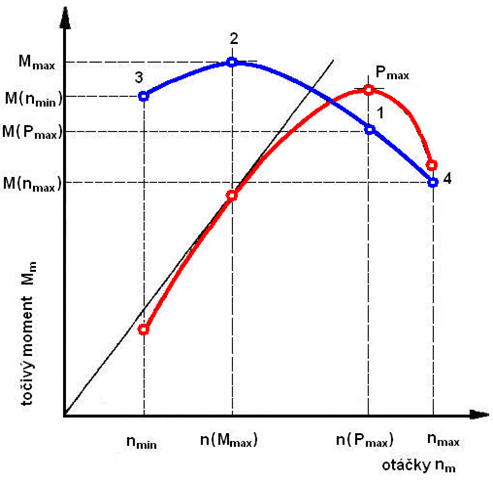

**Vlastnosti vnější rychlostní charakteristiky motoru se vyjadřují několika ukazateli.** 

- **momentová pružnost**


$$${e_M} = \frac{{{M_{\max }}}}{{M({P_{\max }})}}$$$


pro zážehové motory 1,07 – 1,50 

pro vznětové motory 1,03 – 1,35 

- **otáčková pružnost**


$$${e_n} = \frac{{n({P_{\max }})}}{{n({M_{\max }})}}$$$


pro zážehové motory 1,5 – 3,5 

pro vznětové motory  1,3 – 2,0 

- **celková pružnost motoru **


$$${e_m} = {e_M}{e_n}$$$


pro zážehové motory 1,6 – 5,25 

pro vznětové motory  1,34 – 2,7 

### Příklad změřené vnější rychlostní charakteristiky vznětového motoru

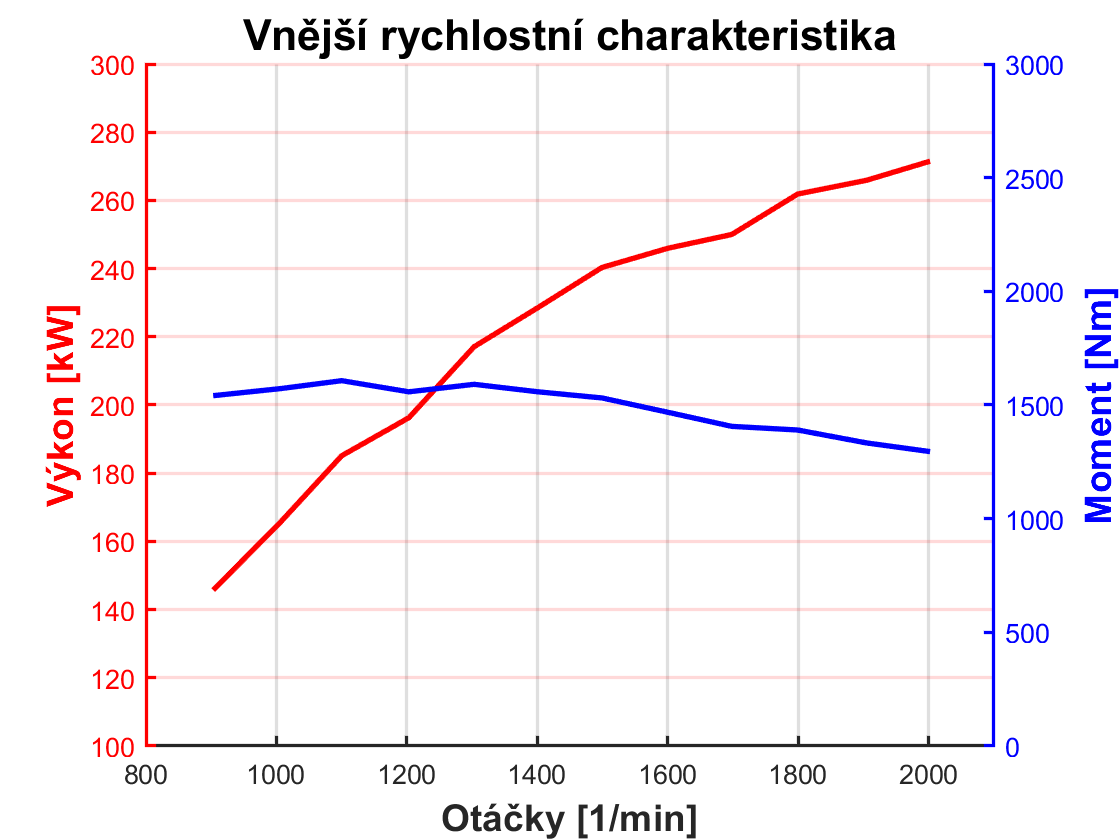


OtackyM1 = [903;1006;1100;1203;1303;1401;1499;1600;1698;1799;1905;2002];
MomentM1 = [1541;1572;1607;1558;1591;1558;1531;1468;1406;1390;1333;1295];
SpotrebaM1 = [36.31;38.86;42.26;43.99;47.31;49.35;51.57;52.94;54.02;56.86;58.90;60.81];

figure;
set(gca, 'linewidth',1.2);
title('Vnější rychlostní charakteristika','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
Vykon = (2*pi/60).*OtackyM1.*MomentM1;
MernaSpotreba = kg2g(SpotrebaM1)./W2kW(Vykon);
hold on
yyaxis left
plot(OtackyM1, W2kW(Vykon),'-r','linewidth',2)
yyaxis right
plot(OtackyM1, MomentM1,'-b','linewidth',2)
hold off
grid on;
%legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([100 300]);
ylabel('Výkon [kW]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','r');
yyaxis right;
ylim([0 3000]);
ylabel('Moment [Nm]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','b');

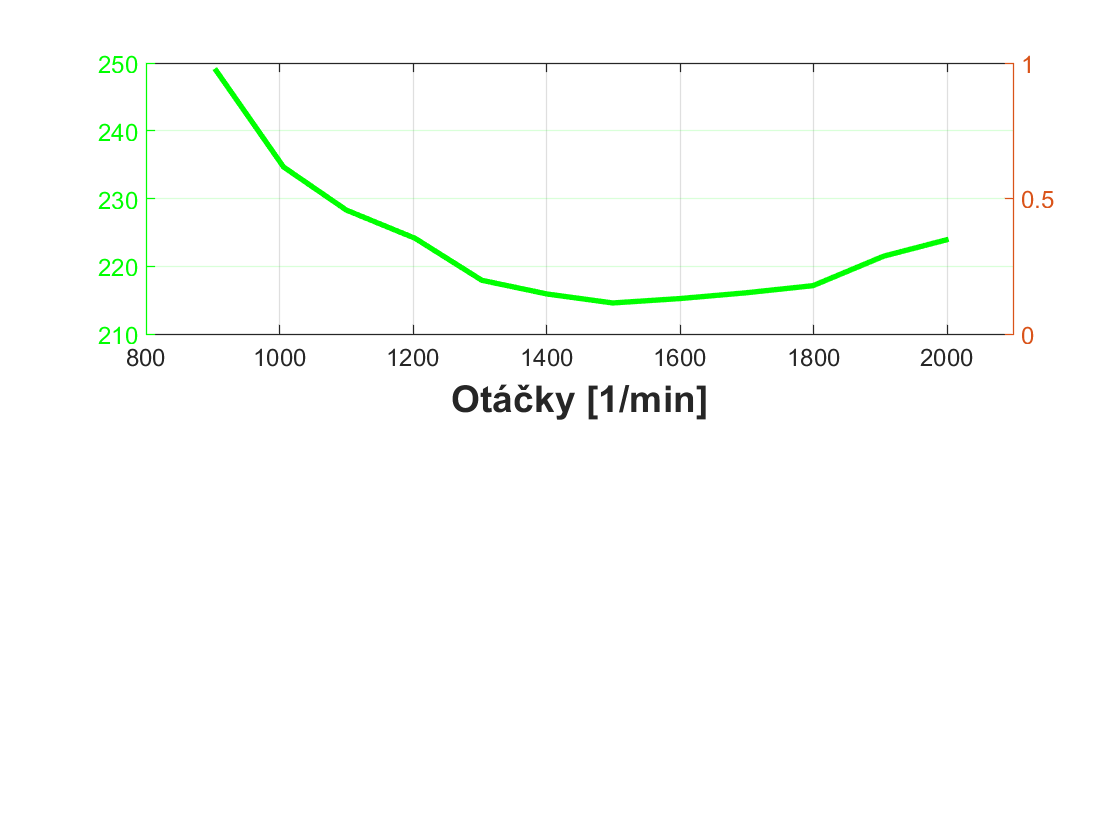

figure;
subplot(2,1,1);
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([180 300]);
ylabel('Měrná spotřeba [g/kgh]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','g');
plot(OtackyM1,MernaSpotreba,'-g','linewidth',2);
grid on;

[Mmax,IMmax] = max(MomentM1);
[Pmax,IPmax] = max(Vykon);
MomentovaPruznost = Mmax/MomentM1(IPmax)

MomentovaPruznost = 1.2409

OtackovaPruznost = OtackyM1(IPmax)/OtackyM1(IMmax)

OtackovaPruznost = 1.8200

CelkovaPruznost = MomentovaPruznost*OtackovaPruznost

CelkovaPruznost = 2.2585

### Vyhlazený graf vnější rychlostní charakteristiky

Pozor vyhlazujeme měřené veličiny, nikoliv počítané. Po vyhlazení lze vyhodnotit požadované veličiny a případně data převzorkovat pro zobrazení v tabulce.

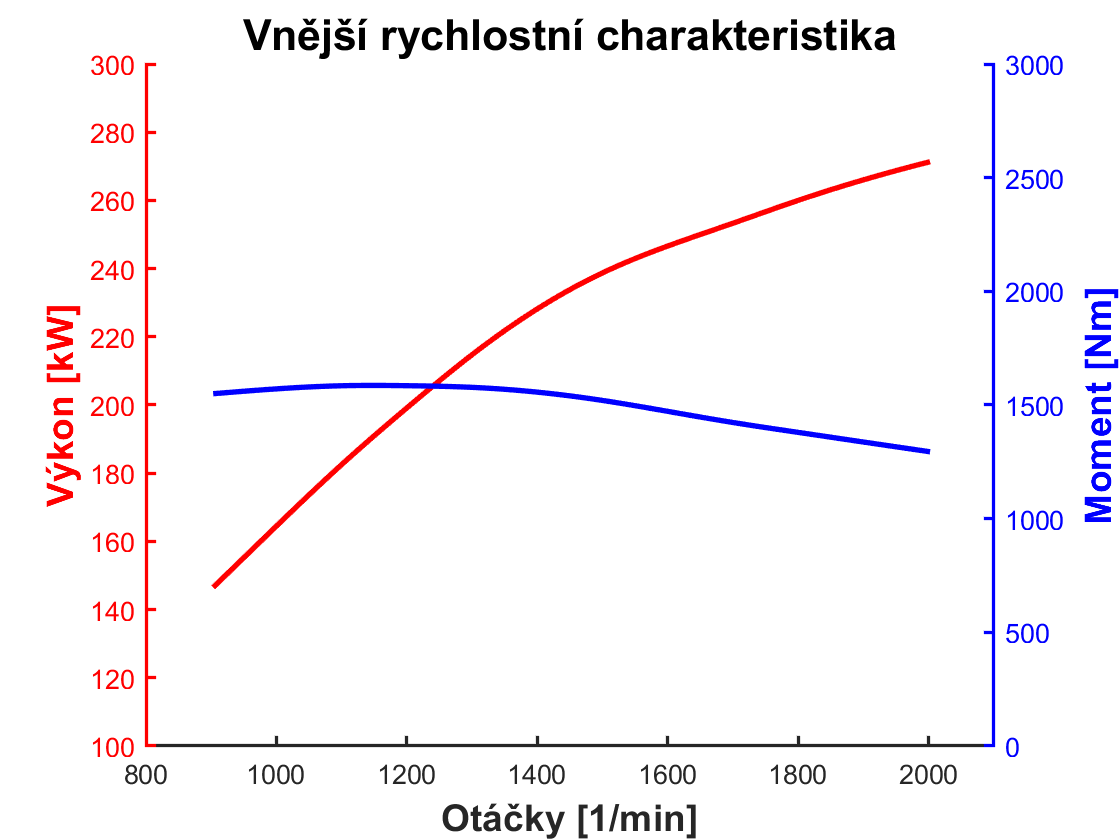

figure;
set(gca, 'linewidth',1.2);
title('Vnější rychlostní charakteristika','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
[ii,jj] = size(OtackyM1);
PocetJemne = ii*10;
OtackyJemne  = linspace(OtackyM1(1),OtackyM1(ii),PocetJemne);
%MomentJemne = polyval(p,OtackyJemne);
yy = zeros(length(OtackyJemne));
p = 0.000001; % Čím nižší číslo tím větší vyhlazení
   MomentJemne = csaps(OtackyM1,MomentM1,p,OtackyJemne);
VykonJemne = (2*pi/60).*OtackyJemne.*MomentJemne;   
hold on
yyaxis left
plot(OtackyJemne, W2kW(VykonJemne),'-r','linewidth',2)
yyaxis right
plot(OtackyJemne, MomentJemne,'-b','linewidth',2)
hold off;
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([800 2100]);
yyaxis left;
ylim([100 300]);
ylabel('Výkon [kW]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','r');
yyaxis right;
ylim([0 3000]);
ylabel('Moment [Nm]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
set(gca,'ycolor','b');

Otacky = OtackyJemne(1):200:OtackyJemne(end);
Moment = spline(OtackyJemne,MomentJemne, Otacky);


T = table(Otacky',Moment');

T

T = 6×2 table
    Var1     Var2 
    ____    ______

     903    1549.6
    1103    1584.8
    1303    1577.2
    1503    1518.7
    1703    1421.6
    1903    1335.8


### **KOREKCE NA ATMOSFERICKÉ PODMÍNKY**

•**ČSN 30 2008**

•**ISO DIS 1585**

•**SAE J 1349****(USA)**  

•**ECE R85**

•**JIS D 1001**

•**DIN 70020**


$$K=\left(\frac{p_{b\_VT}-a∙\phi _{b\_VT}∙p_{p\_VT}}{p_{b\_NT}-a∙\phi _{b\_NT}∙p_{b\_NT} }\right)^m∙\left(\frac{T_{b\_VT}}{T_{b\_NT}}\right)^n∙\left(\frac{T_{w\_VT}}{T_{w\_NT} }\right)^q$$


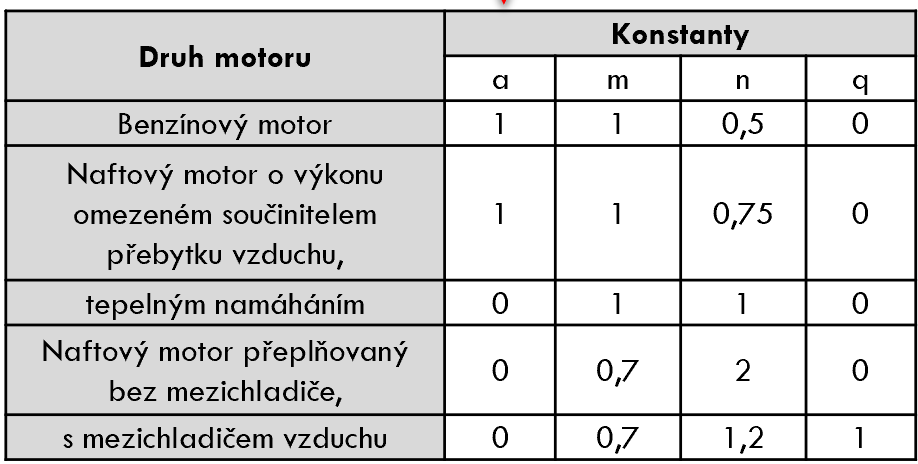


$$P_{kor}= P_{e\_VT}∙\left[K-0,7∙(1-K)∙(1/\eta_m -1)\right]}$$$


### Lokální funkce 

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod kg

function [g] = kg2g(kg)
g = kg * 1000.0;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end